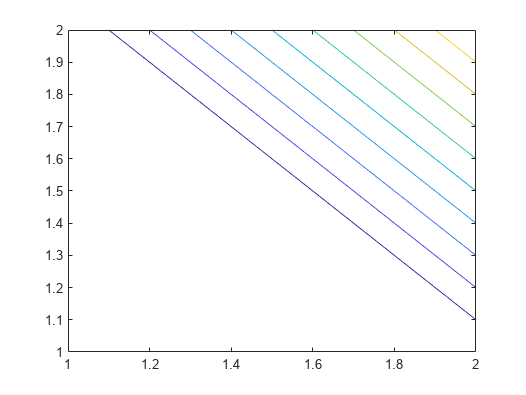

%% Q1 Display contour plots for an AND unit
clear;
x =[0 1];
y =[0 1]';
[X, Y] = meshgrid(x, y);
contour(and(X, Y))

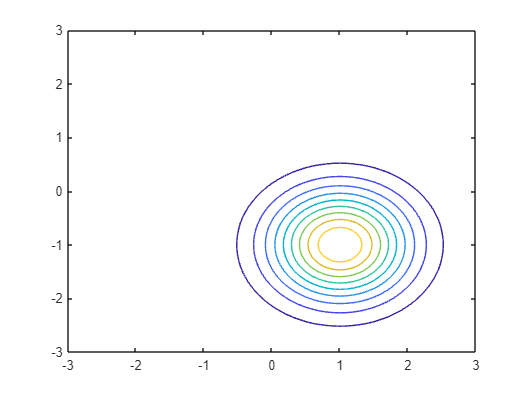


%% Q2 Create a contour plot for a Gaussian (radial unit), showing circular contours

clear;
% code from SingleUnit.ppt Pg. 26
[x, y]=meshgrid(-3:.1:3);
for j=1:61
    for k=1:61
        z(j,k)=rbu([x(j,k),y(j,k)],[1,-1]);
    end
end
figure Name Gaussian1
contour(x,y,z)

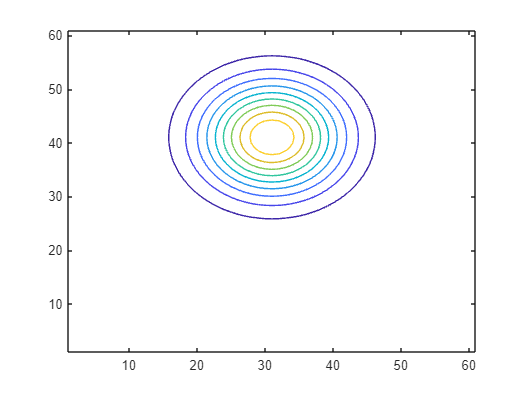


%% Q3 Create a function that will plot a contour plot of the sum of two Gaussians.
[x, y]=meshgrid(-3:.1:3);
for a=1:61
    for b=1:61
        z1(a,b)=rbu([x(a,b),y(a,b)],[0,1]); % picked a different proto
    end
end

figure Name Gaussian2
contour(z1);

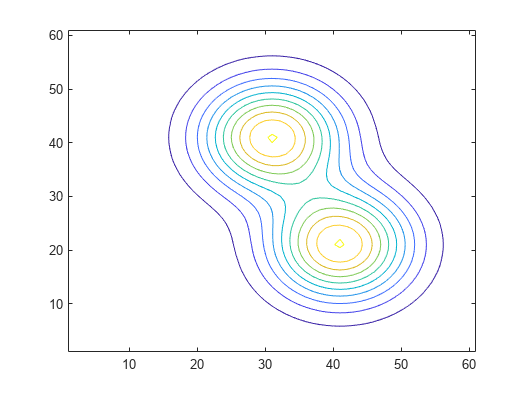

zSum = z+z1; % add them together
figure Name Gaussian1+2
contour(zSum)


%% Q3 Find weight and bias parameters for an LTU that computes the NAND function. (demonstrate in Matlab)

clear;
x = [0 0 1 1; 0 1 0 1];
t = [1 1 1 0];
net = perceptron;
net = train(net,x,t);

net.IW

ans = 1×1 cell array
    {[-2 -1]}


net.b

ans = 1×1 cell array
    {[2]}




%% Q4 Find weights and bias parameters for a 6-input unit that responds with a 1 to (0 0 1 1 0 1) and 0 to all other inputs.
clear;

% generate all possible combination of a input 6
x=ff2n(6)';

t = zeros(1,64);
t(14)=1; % output of 0 0 1 1 0 1 == 1

net = perceptron;
net = train(net,x,t);
net.b

ans = 1×1 cell array
    {[-3]}


net.IW

ans = 1×1 cell array
    {[-3 -4 1 1 -4 1]}




%% Q5* Find weights and bias parameters for a 6-input unit that responds with a 1 to (0 0 1 1 0 1) AND TO (1 0 1 1 0 1) and 0 to all other inputs.

clear;
% generate all possible combination of a input 6
x=ff2n(6)'

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1
     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     0     0
     0     0     0     0     1     1     1     1     0     0     0     0     1     1     1   

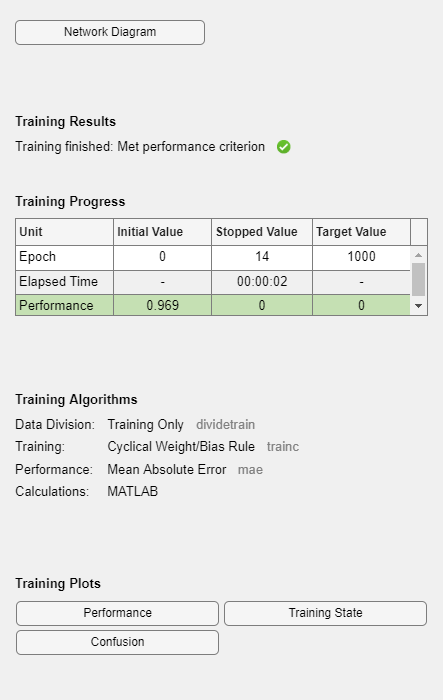


t = zeros(1,64);
t(14)=1; % output of 0 0 1 1 0 1 == 1
t(46)=1; % output of 1 0 1 1 0 1 == 1

net = perceptron;
net = train(net,x,t);

net.b

ans = 1×1 cell array
    {[-7]}


net.IW

ans = 1×1 cell array
    {[0 -5 3 3 -5 1]}



%% Attachment
% Radial units funciton from SingleUnit.ppt Pg. 25

function rr = rbu( ss, proto )
% radial basis unit
% exponential of negative squared distance bewteen ss and proto
rr = exp(-sum((ss-proto).*(ss-proto))) ;
end


% LTU funciton from SingleUnit.ppt Pg. 17
function rr = ltu( ss, upar )
xx = upar.w*ss+upar.b ;
rr = (xx>=0)+0 ;
end


% LTU field funciton from SingleUnit.ppt Pg. 18
function rc = ltufield(unit,gpts)
[xc,yc]=meshgrid(gpts) ;
rc=unit.w(1)*xc+unit.w(2)*yc + unit.b;
figure
contourf(xc,yc,rc,[0 0],'ShowText','on') ;
hold on
plot([0 unit.w(1)],[0 unit.w(2)],'LineWidth',3)
quiver(0,0,unit.w(1),unit.w(2),0,'LineWidth',3,MaxHeadSize=0.9)
axis equal
end


% LTU field funciton from SingleUnit.ppt Pg. 32
function rf = rfieldltu( w,b,xpts,ypts )
plot([0 w(1)],[0 w(2)])
hold on
[xf, yf]=meshgrid(xpts,ypts) ;
vf=w(1)*xf+w(2)*yf+b ;
rf=vf;
contour(xf,yf,rf,[0 0])
end
